# The effect of extra zeros and poles

If there are no zeros then we can approximate the time-domain specifications as follows:

- Rise time $t_r \simeq \frac{1.8}{\omega_n}$

- Overshoot $M_p \simeq \exp \left( \frac{-\pi\zeta}{\sqrt{1 - \zeta^2}} \right)$

- Settling time (1%) $t_s \simeq \frac{4.6}{\sigma}$, (5%) $t_s \simeq \frac{3.0}{\sigma}$.

But if there are extra zeros or poles, then these approximations may be in correct.

This example demonstrates how extra zeros and poles affect the time-domain specifications.

## Extra zeros

First let's make the Laplace variable.  We may want to use it later.

s = tf('s');    % the Laplace variable

### The "ideal" system

The model system we used to relate pole position to time-domain specifications was


$$G_\text{ideal}(s) = \frac{\omega_n^2}{s^2 + 2 \zeta \omega_n s + \omega_n^2}$$


Here we will define $\sigma = 1$.

sigma = 1;      % real part of the pole
tau = 1/sigma;  % time constant

The damping ratio we will try changing.

zeta =  0.5; % damping ratio

Finally define the natural frequency and the "ideal" system transfer function

omega_n = sigma/zeta;   % natural frequency
Gideal = tf(omega_n^2,[ 1 2*zeta*omega_n omega_n^2 ]);

### The system with an extra zero

We will add an extra zero to the ideal system like this


$$G_\text{extra} = \frac{\omega_n^2 ( s/\alpha + 1)}{ s^2 + 2 \zeta \omega_n s + \omega_n^2}$$


This adds a zero at $z = -\alpha$.  Thus, positive values of $\alpha$ make LHP zeros, while negative values of $\alpha$ make RHP zeros.  To avoid division by zeros $\alpha \neq 0$.

### How an extra zero affects the response

If there is a zero in the LHP then

- If it is **slow** $|z| < 4\sigma
$ then it will **increase overshoot.**

- If it is fast $|z| > 4\sigma$ then it will not have much effect.

If there is a zero in the RHP then

- If it is **slow** $|z| < 4\sigma$ then it will depress **add delay, overshoot, cause the system to move initially in the wrong direction. **

- If it is fast $|z| > 4\sigma$ then it will not have much effect.

Note that the boundary between "fast" and "slow" is approximate.

alpha = -2;

switch sign(alpha)
    case 0 % alpha == 0
        error('alpha must be non-zero.')
    case 1 % LHP zero
        if abs(alpha) < 4,  % slow zero
            disp('Slow LHP zero')
            disp('Increase overshoot.')
        else
            disp('Fast LHP zero.')
            disp('Little effect.')
        end
    case -1 % RHP zero
        if abs(alpha) < 4,  % slow zero
            disp('Slow RHP zero.')
            disp('Start in wrong direction, increased delay, decreased overshoot.')
        else
            disp('Fast RHP zero.')
            disp('Little effect.')
        end
end

Slow RHP zero.


Start in wrong direction, increased delay, decreased overshoot.


Gextra = Gideal*(s/alpha + 1 );

### Pole-zero map

Here is a pole-zero map of the two systems.  The poles lie on top of each other.  There are vertical lines at $x \pm 4$to show when the zero is "fast" or "slow" --- between the lines is slow.

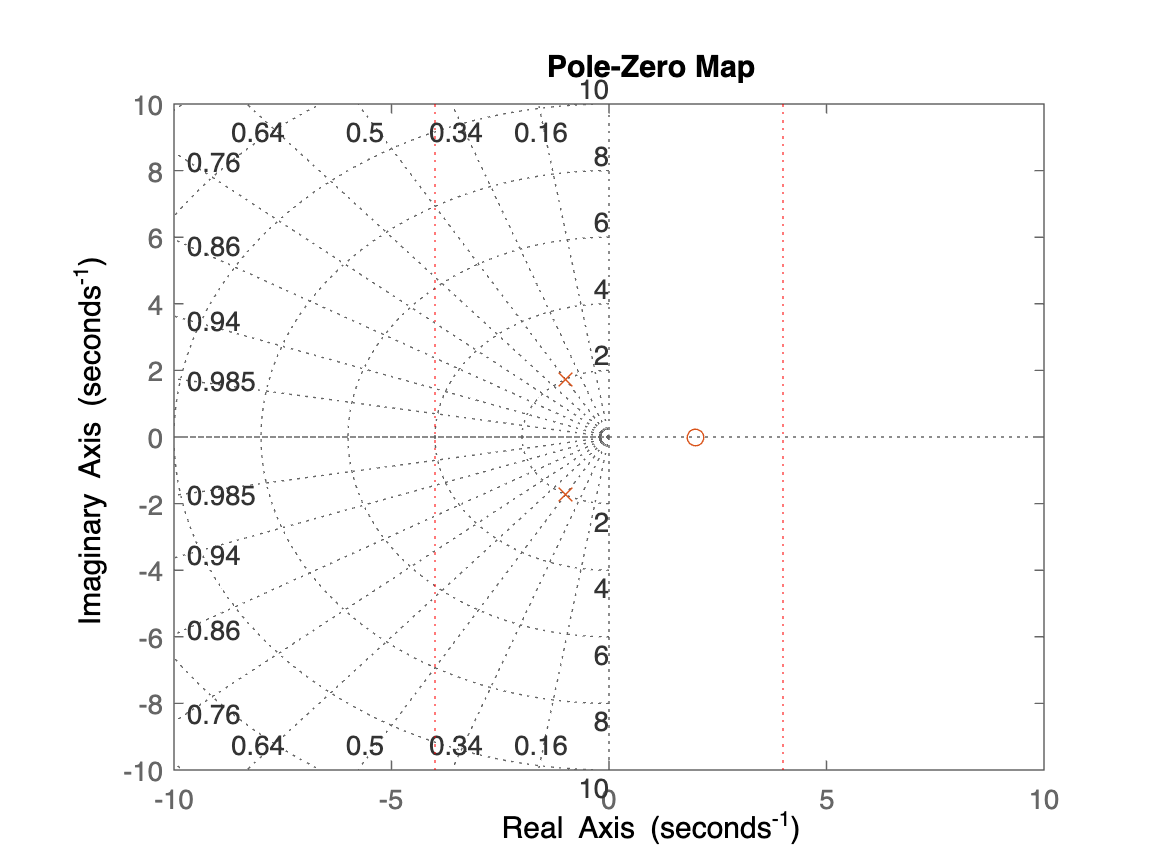

pzplot(Gideal,Gextra)
axis([ -10 10 -10 10 ])

xline(-4,'r:'),xline(+4,'r:')
grid on

### Step response

Compute a step response for both systems and compare them.

Tfinal = 8*tau;
time = linspace(0,Tfinal,10001);
[y_ideal] = step(Gideal,time);
[y_extra] = step(Gextra,time);

Using the real response we can fine the time-domain specs.

Note:  

- The settling time is a 5% settling time.

- The overshoot is in units of percent (%).

specs_ideal = stepinfo(y_ideal,time,1,'SettlingTimeThreshold',0.05)

specs_ideal = struct with fields:
         RiseTime: 0.8188
    TransientTime: 2.6445
     SettlingTime: 2.6445
      SettlingMin: 0.9002
      SettlingMax: 1.1630
        Overshoot: 16.3034
       Undershoot: 0
             Peak: 1.1630
         PeakTime: 1.8136

specs_extra = stepinfo(y_extra,time,1,'SettlingTimeThreshold',0.05)

specs_extra = struct with fields:
         RiseTime: 0.6331
    TransientTime: 2.9468
     SettlingTime: 3.0161
      SettlingMin: 0.9001
      SettlingMax: 1.2087
        Overshoot: 20.8713
       Undershoot: 28.0187
             Peak: 1.2087
         PeakTime: 2.1160

IMPORTANT!!!  The settling time the **stepinfo** function calculates **is wrong** if the overshoot is greater than 100%.  I have no idea why this is the case.  This is an example of why you should be very careful to used canned programs to calculate things.  You never know if the other person wrote the program correctly.  In this case, you would have an overly optimistic estimate of the settling time.  To be honest, other values may be wrong too, but I have neither noticed a problem nor debugged them.

ts_ideal = time(find(abs(y_ideal - 1) > 0.05,1,'last'))

ts_ideal = 2.6440

ts_extra = time(find(abs(y_extra - 1) > 0.05,1,'last'))

ts_extra = 3.0160

Now let's plot everything together.

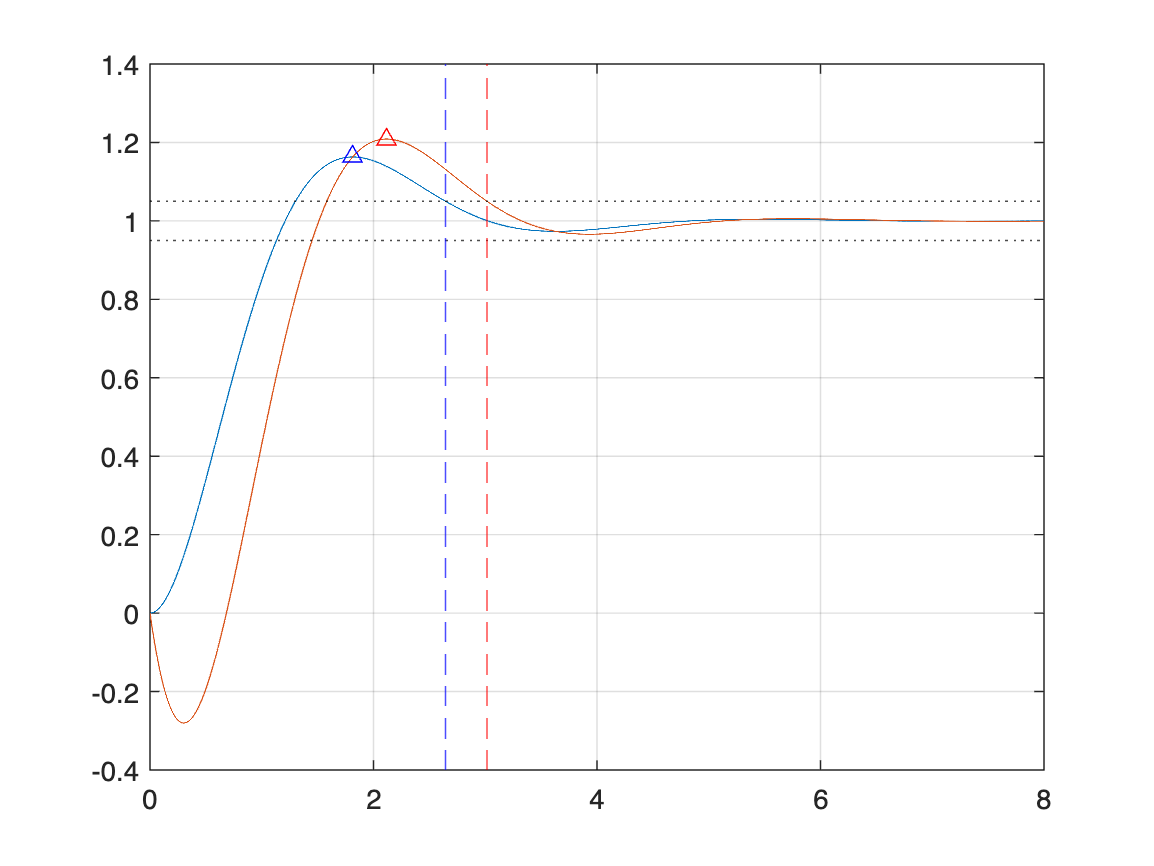

plot(time,y_ideal,time,y_extra, ...
    specs_ideal.PeakTime,1+specs_ideal.Overshoot/100,'b^',...
    specs_extra.PeakTime,1+specs_extra.Overshoot/100,'r^')

% plot some error bounds for 5% error
yline(1.05,'k:'), yline(0.95,'k:')

% plot the settling time for the ideal and extra transfer functions
xline(ts_ideal,'b--')
xline(ts_extra,'r--')
% xline(ts_extra,'r--')

grid on

Try running this code for different values of $\alpha$.

- $\alpha = 10$ fast LHP zero

- $\alpha = 4$ borderline fast/slow LHP zero

- $\alpha = 0.5
$ slow LHP zero

- $\alpha = -0.5
$ slow RHP zero

- $\alpha = -4
$ borderline fast/slow RHP zero

- $\alpha = -10$ fast RHP zero

Do the general trends outlined in "How a zero affects the response" hold?

## Extra poles

#### The system with an extra pole

We will add an extra zero to the ideal system like this


$$G_\text{extra} = \frac{\omega_n^2 }{ ( s^2 + 2 \zeta \omega_n s + \omega_n^2 ) ( s/p + 1) }$$


This adds a zero at $z = -p$.  Thus, for the system to be stable $p > 0$.

### How an extra pole affects the response

If there is a zero in the LHP then

- If it is **slow** $p < 4\sigma
$ then it will **increase rise time.**

- If it is fast $z > 4\sigma$ then it will not have much effect.

If there is a zero in the RHP then

- It's unstable.

Note that the boundary between "fast" and "slow" is approximate.

p = 1;

switch sign(p)
    case 0 % alpha == 0
        error('alpha must be non-zero.')
    case -1 % RHP zero
        error('Unstable.  The pole must be in the LHP.')
    case 1 % LHP zero
        if p < 4,  % slow zero
            disp('Slow LHP pole.')
            disp('Increase rise time.')
        else
            disp('Fast LHP zero.')
            disp('Little effect.')
        end
end

Slow LHP pole.


Increase rise time.


Gextra = Gideal/(s/p + 1 );

### Pole-zero map

Here is a pole-zero map of the two systems.  The poles lie on top of each other.  There are vertical lines at $x \pm 4$to show when the zero is "fast" or "slow" --- between the lines is slow.

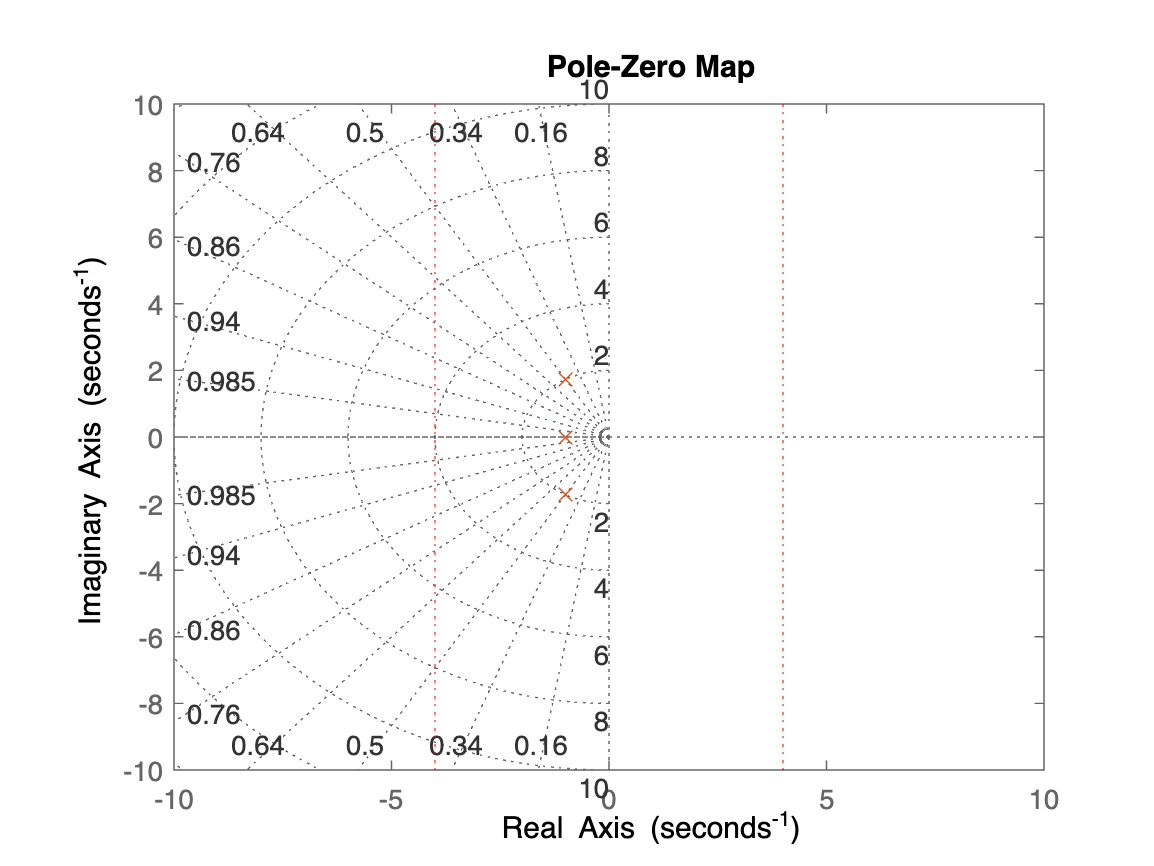

pzplot(Gideal,Gextra)
axis([ -10 10 -10 10 ])

xline(-4,'r:'),xline(+4,'r:')
grid on

### Step response

Compute a step response for both systems and compare them.

Tfinal = 8*tau;
time = linspace(0,Tfinal,10001);
[y_ideal] = step(Gideal,time);
[y_extra] = step(Gextra,time);

Using the real response we can fine the time-domain specs.

Note:  

- The settling time is a 5% settling time.

- The overshoot is in units of percent (%).

specs_ideal = stepinfo(y_ideal,time,1,'SettlingTimeThreshold',0.05)

specs_ideal = struct with fields:
         RiseTime: 0.8188
    TransientTime: 2.6445
     SettlingTime: 2.6445
      SettlingMin: 0.9002
      SettlingMax: 1.1630
        Overshoot: 16.3034
       Undershoot: 0
             Peak: 1.1630
         PeakTime: 1.8136

specs_extra = stepinfo(y_extra,time,1,'SettlingTimeThreshold',0.05)

specs_extra = struct with fields:
         RiseTime: 1.7278
    TransientTime: 2.7180
     SettlingTime: 2.7180
      SettlingMin: 0.9001
      SettlingMax: 0.9994
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9994
         PeakTime: 8

IMPORTANT!!!  The values calculated above use the stepinfo function.  The settling time the **stepinfo** function calculates **is wrong** if the overshoot is greater than 100%.  I have no idea why this is the case.  This is an example of why you should be very careful to used canned programs to calculate things.  You never know if the other person wrote the program correctly.  In this case, you would have an overly optimistic estimate of the settling time.  To be honest, other values may be wrong too, but I have neither noticed a problem nor debugged them.

ts_ideal = time(find(abs(y_ideal - 1) > 0.05,1,'last'))

ts_ideal = 2.6440

ts_extra = time(find(abs(y_extra - 1) > 0.05,1,'last'))

ts_extra = 2.7176

Now let's plot everything together.

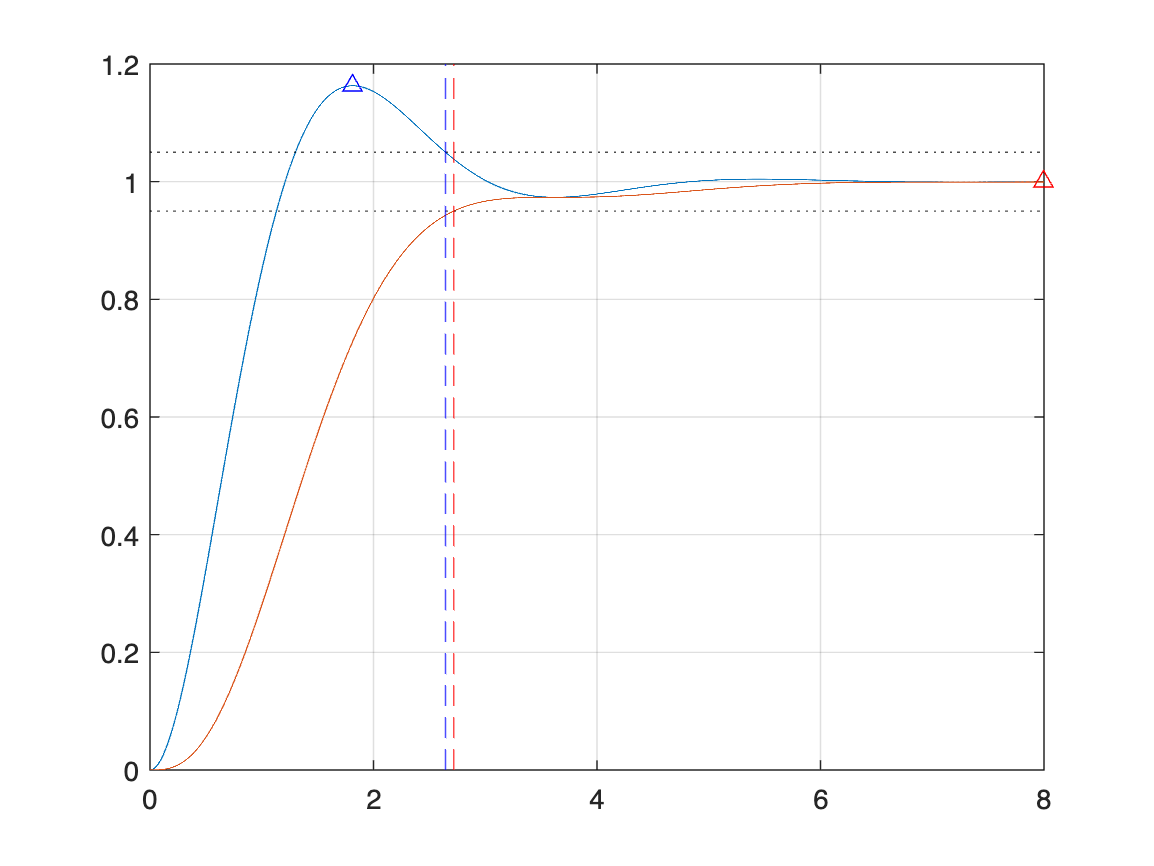

plot(time,y_ideal,time,y_extra, ...
    specs_ideal.PeakTime,1+specs_ideal.Overshoot/100,'b^',...
    specs_extra.PeakTime,1+specs_extra.Overshoot/100,'r^')

% plot some error bounds for 5% error
yline(1.05,'k:'), yline(0.95,'k:')

% plot the settling time for the ideal and extra transfer functions
xline(ts_ideal,'b--')
xline(ts_extra,'r--')
% xline(ts_extra,'r--')

grid on

Try running this code for different values of $\alpha$.

- $p = 10$ fast LHP pole

- $p = 4$ borderline fast/slow LHP pole

- $p = 0.5
$ slow LHP pole

Do the general trends outlined in "How a pole affects the response" hold?